### **Иван Шаламов, 551 группа. Лабораторная работа № 2, 2020.**

% TODO: 1) ode45 считать по другому времени (либо подбором, 
% либо считать методом Ньютона, методом пристрелки). 
% 2) Понять, как поместить целое слово в нижний индекс - {}.

clc;
close all;
clear;
opengl software;

### **Практическая часть.**

Общие параметры задачи.

TextSize = 15; % размер шрифта

K = 0.3; % аэродинамическое качесто
rz = 6.37e6; % радиус Земли, м
sigma = 0.01; % баллистический параметр (C_x * S / m)
g0 = 9.81; % ускорение свободного падения на поверхности земли, м/с^2
rho0 = 1.23; % плотность воздуха на поверхности земли, кг/м^3

Начальные условия и шаг интегрирования.

dt = 5; % шаг интегрирования

v0 = 7800; % скорость входа, м/с
theta0 = 0 * pi / 180; % угол входа, рад
x0 = 0; % начальная координата, м
h0 = 80000; % высота точки начала интегрирования (точки входа), м
t0 = 0; % начальное время, с
Y0 = [v0 theta0 x0 h0]; % вектор входных параметров

Интегрирование системы уравнений методом Эйлера первого порядка (до достижения Земли: h = 0).

i = 1; % индекс элемента
Y1(i,:) = Y0;
T1(i) = t0;

while Y1(i,4) > 0
    
    T1(i+1) = T1(i) + dt;
    Y1(i+1,:) = Y1(i,:) + dt * RightPart(T1(i), Y1(i,:), rho0, g0, rz, sigma, K)';
    i = i + 1;
    
end

Интегрирование системы уравнений усовершенствованным методом Эйлера второго порядка (до достижения Земли: h = 0).

i = 1; % индекс элемента
Y2(i,:) = [v0 theta0 x0 h0]; % вектор входных параметров
T2(i) = t0;

while Y2(i,4) > 0
    
    T2(i+1) = T2(i) + dt;
    Y2(i+1,:) = Y2(i,:) + dt * (RightPart(T2(i), Y2(i,:), rho0, g0, rz, sigma, K)' + ...
        RightPart(T2(i), Y2(i,:) + dt * ...
        RightPart(T2(i), Y2(i,:), rho0, g0, rz, sigma, K)', rho0, g0, rz, sigma, K)') / 2;
    i = i + 1;
    
end

### **Исследовательская часть.**

Решение системы ОДУ с использованием библиотечной функции MATLAB.

% Функция, основанная на явной формуле Рунге-Кутты (4, 5) - методе Дормана-Принса:

[T, Y] = ode45(@(t, y) RightPart(t, y, rho0, g0, rz, sigma, K), ...
    linspace(t0, max(T2), length(T2)), Y0);

Вывод графиков.

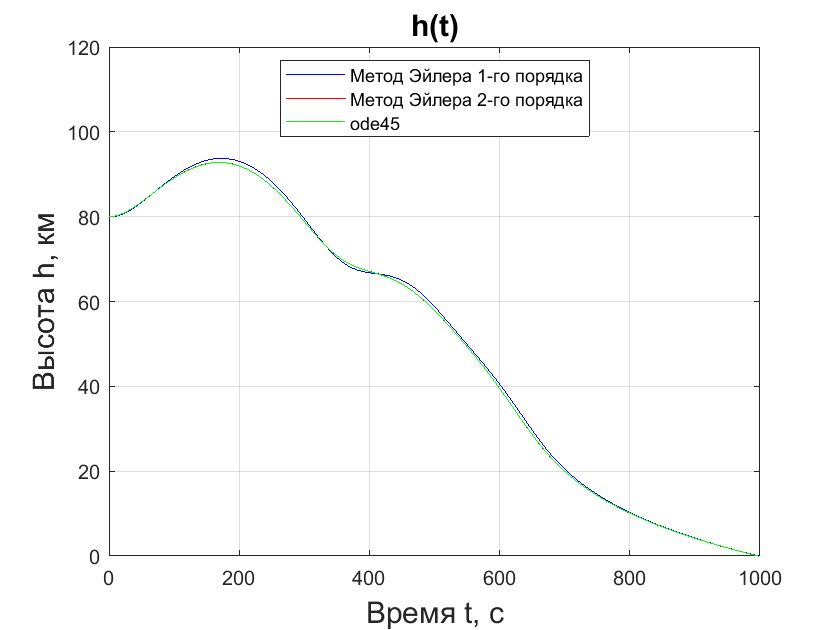

figure(1);
plot(T1, Y1(:,4)/1000, '-b', T2, Y2(:,4)/1000, '-r', T, Y(:,4)/1000, '-g');
grid on;
title('h(t)', 'FontSize', TextSize);
xlabel('Время t, с', 'FontSize', TextSize);
ylabel('Высота h, км','FontSize', TextSize);
xlim([0, max(T2)]);
ylim([0, 1.5*h0/1000]);
legend({'Метод Эйлера 1-го порядка', 'Метод Эйлера 2-го порядка', 'ode45'}, ...
    'Location', 'best');

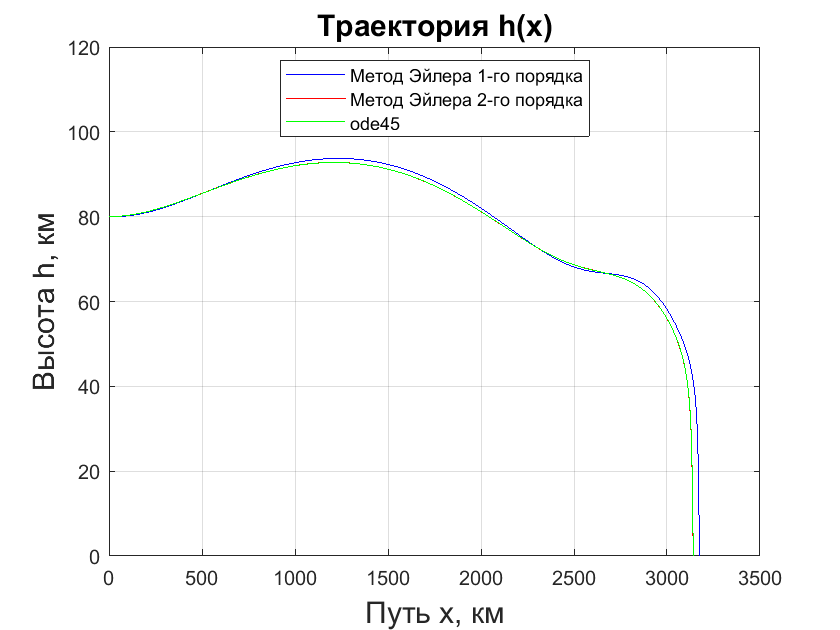


figure(2);
plot(Y1(:,3)/1000, Y1(:,4)/1000, '-b', Y2(:,3)/1000, Y2(:,4)/1000, '-r', ...
    Y(:,3)/1000, Y(:,4)/1000, '-g');
grid on;
title('Траектория h(x)', 'FontSize', TextSize);
xlabel('Путь x, км', 'FontSize', TextSize);
ylabel('Высота h, км', 'FontSize', TextSize);
ylim([0, 1.5*h0/1000]);
legend({'Метод Эйлера 1-го порядка', 'Метод Эйлера 2-го порядка', 'ode45'}, ...
    'Location', 'best');

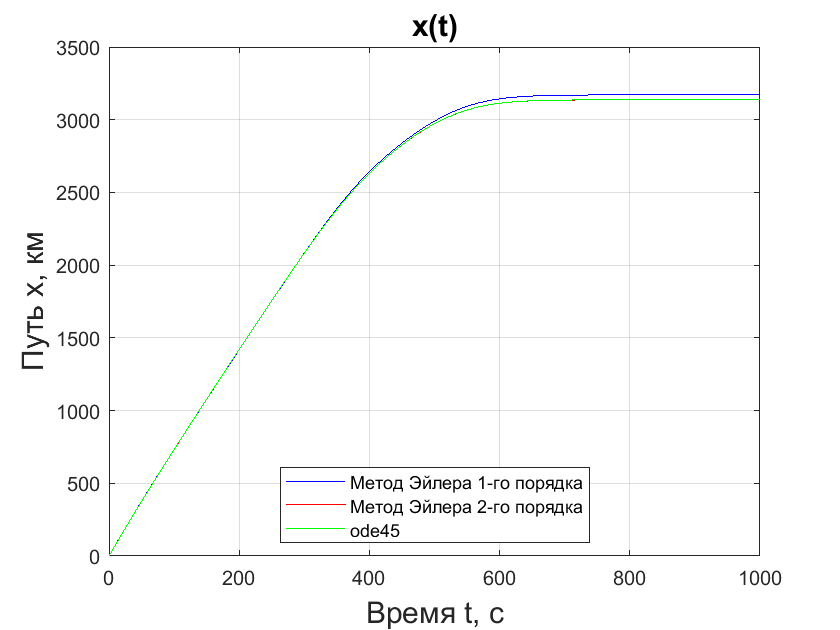


figure(3);
plot(T1, Y1(:,3)/1000, '-b', T2, Y2(:,3)/1000, '-r', T, Y(:,3)/1000, '-g');
grid on;
title('x(t)', 'FontSize', TextSize);
xlabel('Время t, с', 'FontSize', TextSize);
ylabel('Путь x, км', 'FontSize', TextSize);
xlim([0, max(T2)]);
legend({'Метод Эйлера 1-го порядка', 'Метод Эйлера 2-го порядка', 'ode45'}, ...
    'Location', 'best');

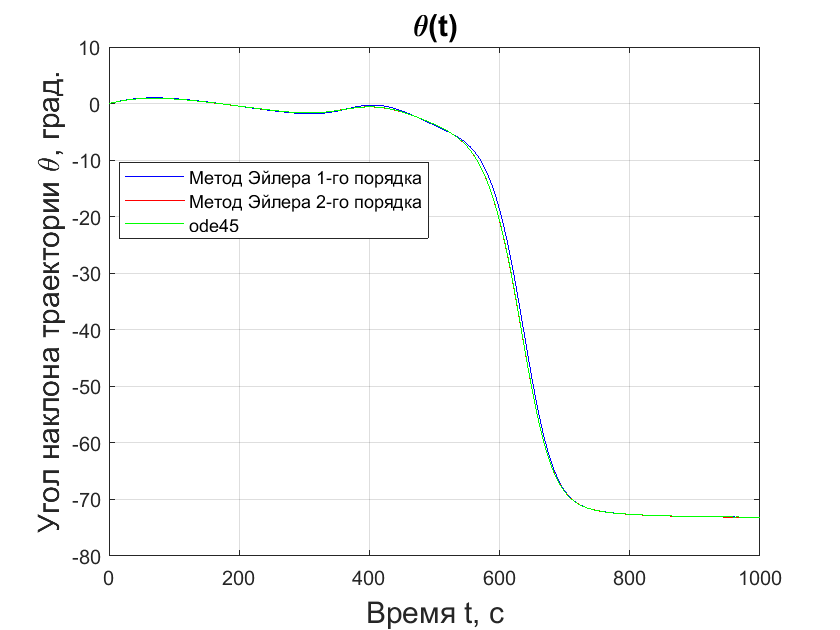


figure(4);
plot(T1, Y1(:,2)*180/pi, '-b', T2, Y2(:,2)*180/pi, '-r', T, Y(:,2)*180/pi, '-g');
grid on;
title('\theta(t)', 'FontSize', TextSize);
xlabel('Время t, с', 'FontSize', TextSize);
ylabel('Угол наклона траектории \theta, град.', 'FontSize', TextSize);
xlim([0, max(T2)]);
legend({'Метод Эйлера 1-го порядка', 'Метод Эйлера 2-го порядка', 'ode45'}, ...
    'Location', 'best');

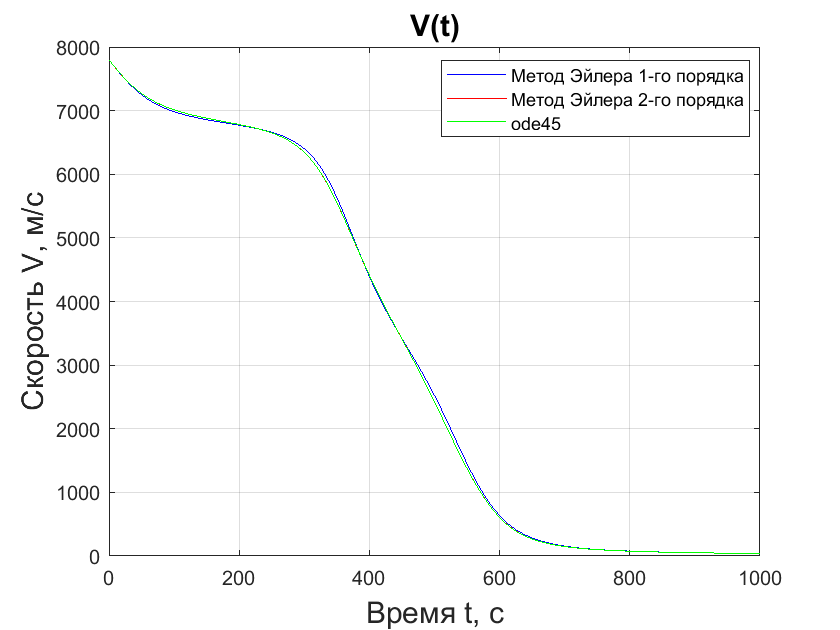


figure(5);
plot(T1, Y1(:,1), '-b', T2, Y2(:,1), '-r', T, Y(:,1), '-g');
grid on;
title('V(t)', 'FontSize', TextSize);
xlabel('Время t, с', 'FontSize', TextSize);
ylabel('Скорость V, м/с', 'FontSize', TextSize);
xlim([0, max(T2)]);
legend({'Метод Эйлера 1-го порядка', 'Метод Эйлера 2-го порядка', 'ode45'}, ...
    'Location', 'best');

Варьирование угла входа. Вычисление максимальной перегрузки на каждой траектории. Вывод графика перегрузки для рассматриваемого варианта. Нахождение траектории, на которой реализуется минимальная перегрузка.

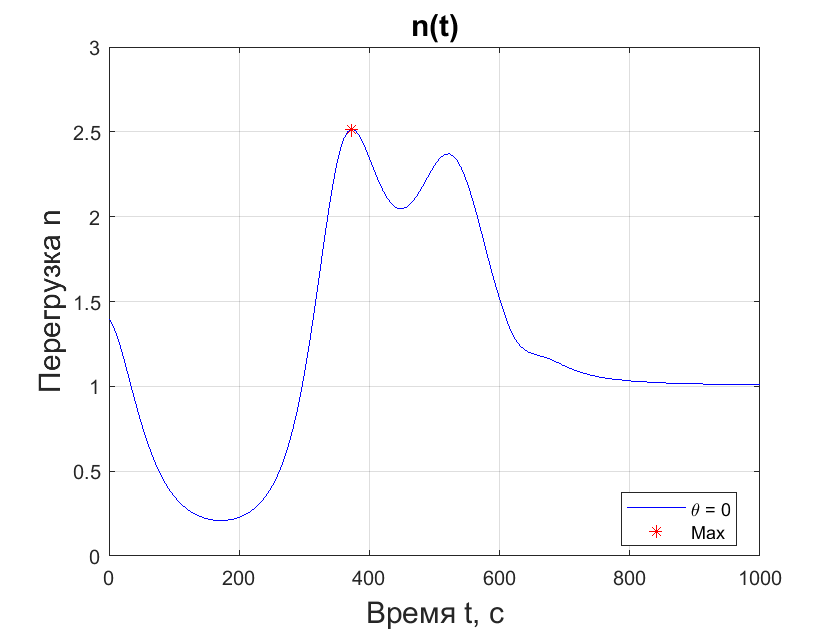

j_left = -5; % левая граница варьирования
j_right = 5; % правая граница варьирования
q = zeros(500, abs(j_right-j_left)); % скоростной напор (кг / (м * с^2)
n_max = zeros(abs(j_right-j_left), 1); % максимальная перегрузка
c = 1; % индекс элемента

for j = j_left:j_right
    
    theta0 = j * pi / 180; % угол входа, рад
    Y0 = [v0 theta0 x0 h0]; % вектор входных параметров 
    
    [TT, YY] = ode45(@(t, y) RightPart(t, y, rho0, g0, rz, sigma, K), ...
        linspace(t0, 3000, 500), Y0);
    q(:,c) = (0.5 * rho0).*exp(-YY(:,4)./7800).*(YY(:,1).^2);
    
    n = sqrt(((sigma.*q(:,c))).^2 + (((sigma * K).*q(:,c))).^2) / g0; % перегрузка
    n_max(c) = max(n);
    
    if j == 0
        
        figure(5);
        plot(TT, n, '-b', TT(n == n_max(c)), n_max(c), 'r*');
        grid on;
        title('n(t)', 'FontSize', TextSize);
        xlabel('Время t, с', 'FontSize', TextSize);
        ylabel('Перегрузка n', 'FontSize', TextSize);
        legend({'\theta = 0', 'Max'}, 'Location', 'best');
        xlim([0, max(T2)]);
        
    end
    
    c = c + 1;
    
end

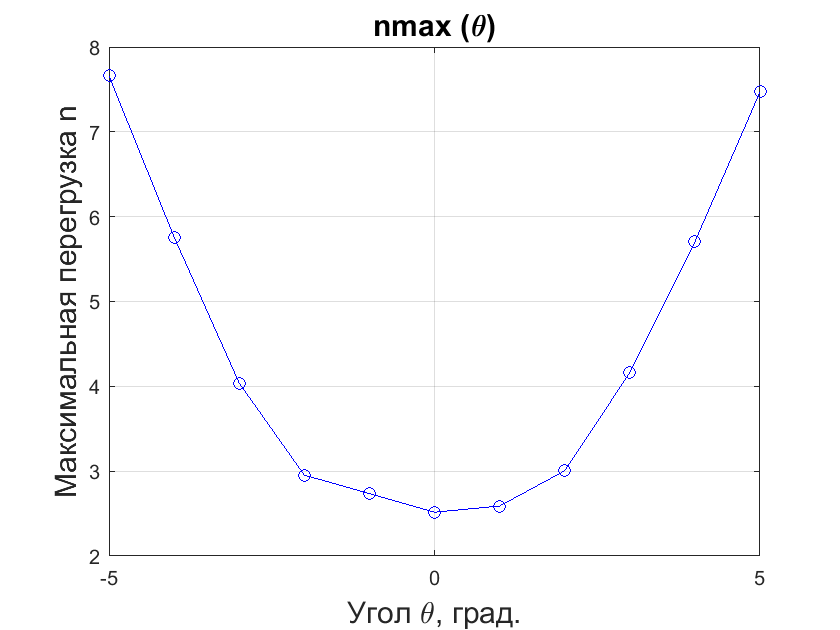


figure(6);
plot(j_left:j_right, n_max, '-bo');
grid on;
title('n max (\theta)', 'FontSize', TextSize);
xlabel('Угол \theta, град.', 'FontSize', TextSize);
ylabel('Максимальная перегрузка n', 'FontSize', TextSize);

[n_min, n_min_ind] = min(n_max); % минимальная перегрузка среди всех траектории

fprintf('При угле входа θ = %d° реализуется минимальная перегрузка n = %.2f g.', ...
    j_left+n_min_ind-1, n_min);

При угле входа θ = 0° реализуется минимальная перегрузка n = 2.52 g.

### **Использованные функции.**

Функция правых частей уравнения движения ЛА в поле Земли.

function F = RightPart(T, Y, rho0, g0, rz, sigma, K)

    V = Y(1); 
    theta = Y(2);
    h = Y(4); % переменные из переданного вектора
    t = T;
    
    rho = rho0 * exp(-h / 7800);
    g = g0 * (rz./(rz + h)).^2; % используемые параметры
    
    F = [-sigma * rho * V^2 / 2 - g * sin(theta);
         (1 / V) * (sigma * K * rho * V^2 / 2 - g * cos(theta) + ...
            V^2 / (rz + h) * cos(theta));
         V * cos(theta); 
         V * sin(theta);]; % правые части

end